Distance of centroid in pp0.jpg: 475.0311


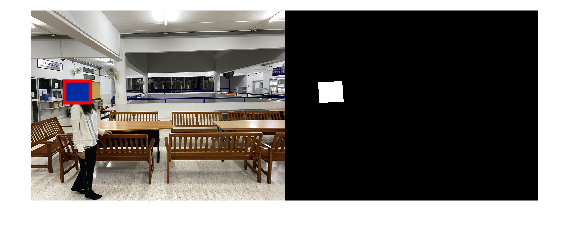

Distance of centroid in pp1.jpg: 388.8991


Distance difference between pp0.jpg and pp1.jpg: 86.132


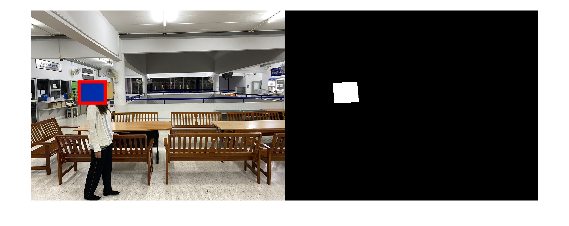

Distance of centroid in pp2.jpg: 328.8199


Distance difference between pp1.jpg and pp2.jpg: 60.0792


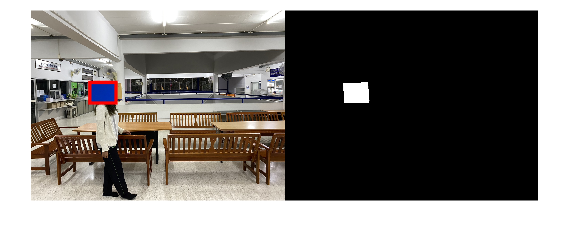

Distance of centroid in pp3.jpg: 256.8472


Distance difference between pp2.jpg and pp3.jpg: 71.9726


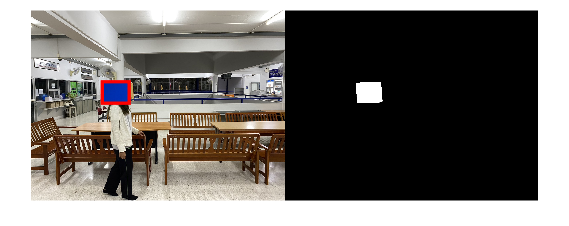

Distance of centroid in pp4.jpg: 204.9158


Distance difference between pp3.jpg and pp4.jpg: 51.9314


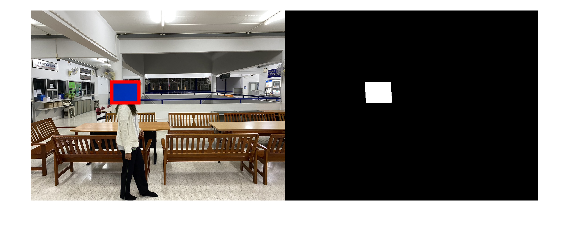

Distance of centroid in pp5.jpg: 129.4005


Distance difference between pp4.jpg and pp5.jpg: 75.5153


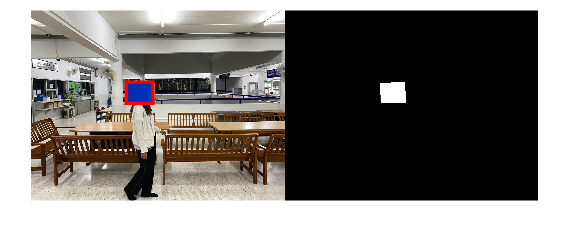

Distance of centroid in pp6.jpg: 84.4541


Distance difference between pp5.jpg and pp6.jpg: 44.9464


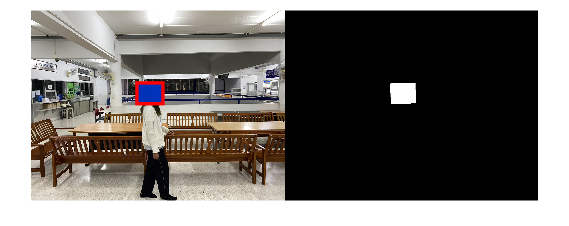

Distance of centroid in pp7.jpg: 90.5124


Distance difference between pp6.jpg and pp7.jpg: 6.0583


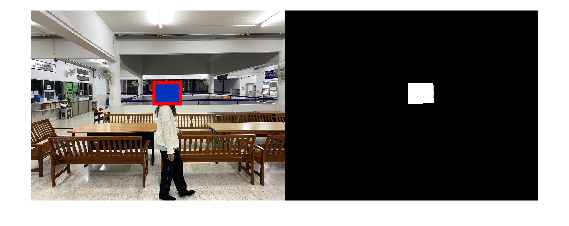

Distance of centroid in pp8.jpg: 169.2705


Distance difference between pp7.jpg and pp8.jpg: 78.7581


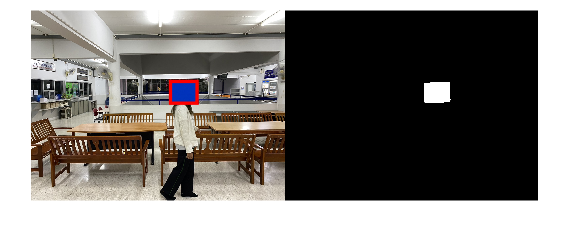

Distance of centroid in pp9.jpg: 250.1649


Distance difference between pp8.jpg and pp9.jpg: 80.8945


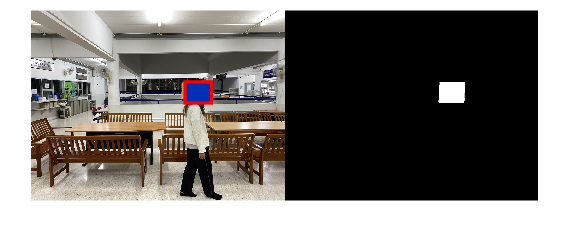

Distance of centroid in pp10.jpg: 345.5351


Distance difference between pp9.jpg and pp10.jpg: 95.3701


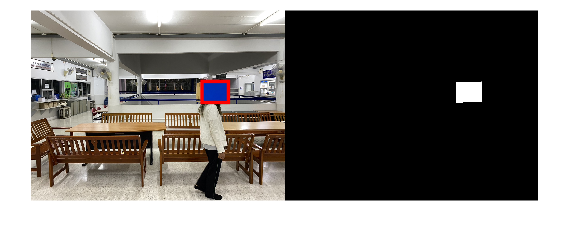

Distance of centroid in pp11.jpg: 426.9666


Distance difference between pp10.jpg and pp11.jpg: 81.4315


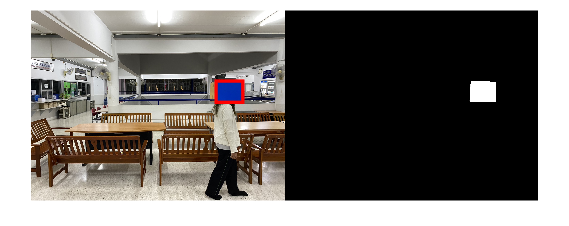

Distance of centroid in pp12.jpg: 564.4382


Distance difference between pp11.jpg and pp12.jpg: 137.4716


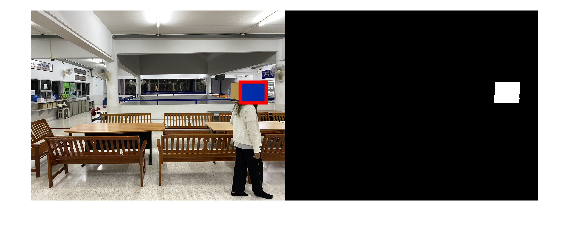

Distance of centroid in pp13.jpg: 643.8078


Distance difference between pp12.jpg and pp13.jpg: 79.3696


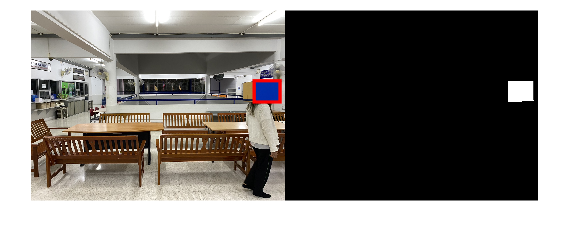

clc
clear all
close all

% Define input folder
inputFolder = 'C:\Users\njsiw\Desktop\dataset2\Original';
GTFolder = 'C:\Users\njsiw\Desktop\dataset2\GroundTruth';
outDirectory = 'C:\Users\njsiw\Desktop\dataset2\Output';


% Get list of JPG files in folder
fileList = dir(fullfile(inputFolder, '*.jpg'));
[~,idx] = sort([fileList.datenum]);
fileList = fileList(idx);

fileList2 = dir(fullfile(GTFolder, '*.jpg'));
[~,idx] = sort([fileList2.datenum]);
fileList2 = fileList2(idx);

fileList3 = numel(fileList);

% Loop over all JPG files in folder
for j = 1:length(fileList)
    
    % Read current input image
    img = imread(fullfile(inputFolder, fileList(j).name));
    
    M2d = im2double(img);

    % Extract red and blue channels
    [R,G,B] = imsplit(M2d);

    % Create a binary image based on the red and blue channels
    [m2, n2] = size(R);
        X = zeros(m2,n2);
         for i = 1:m2
          for k = 1:n2
           if R(i,k) >= 0 && R(i,k) <= 0.20 && G(i,k) <= 0.40  && B(i,k) >= 0.43
            X(i,k) = 255;
           end
          end
         end

    % Apply median filtering to remove noise
    X = medfilt2(X, [3 3]);

    % Convert binary image to grayscale and display
    Mfor = mat2gray(X);

    % Remove small objects
    Mao = bwareaopen(Mfor,1500);

    SE = strel('disk',20);
    Mc = imclose(Mao,SE);

     % Define image size
    imgSize = size(Mc);

    % Extract centroid of white area in Mc
    props = regionprops(Mc, 'Centroid');
    centroid = round(props(1).Centroid);
    centroid_x = centroid(1);
    centroid_y = centroid(2);
    centroidCoords(j,:) = centroid; % store centroid coordinates
    centroid_points(j,:) = [centroid_x, centroid_y];

    % Calculate distance between centroid and center of image
    center = [imgSize(2)/2, imgSize(1)/2];
    distance(j) = norm(centroid - center);

    % Display distance
    disp(['Distance of centroid in ' fileList(j).name ': ' num2str(distance(j))]);

    % Calculate distance difference between this image and the previous one
    if j > 1
        dist_diff = abs(distance(j) - distance(j-1));
        disp(['Distance difference between ' fileList(j-1).name ' and ' fileList(j).name ': ' num2str(dist_diff)]);
    end

    

    % Create Output folder if it does not exist
    if ~exist('Output', 'dir')
        mkdir('Output');
    end

    % Save Mc in Output folder
    imwrite(Mc, fullfile('Output', [fileList(j).name(1:end-4) '_.jpg']));

    g = fullfile(GTFolder,fileList2(j).name);
    gt = imread(g);
    gt = gt(:,:,1);
    gt = logical(gt);


   

    % Check if centroid matches with ground truth pixel
    acc = 0;
    cc = regionprops(Mc, 'Centroid', 'BoundingBox');
    for i = 1:length(cc)
        centroid = round(cc(i).Centroid);
        if gt(centroid(2), centroid(1)) == 1
            acc = 100;
        end
    end

    % Write to Excel file
    save_dir = 'C:\Users\njsiw\Desktop\dataset2\Compare2.xlsx';
    xlswrite(save_dir, {fileList(j).name,acc}, 'Sheet1', ['A' num2str(j)]);

    % Draw bounding box on original image
    figure;
    imshowpair(img,Mc,'montage');
    hold on;
    for i = 1:length(cc)
        bb = cc(i).BoundingBox;
        rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
    end
    hold off;

end

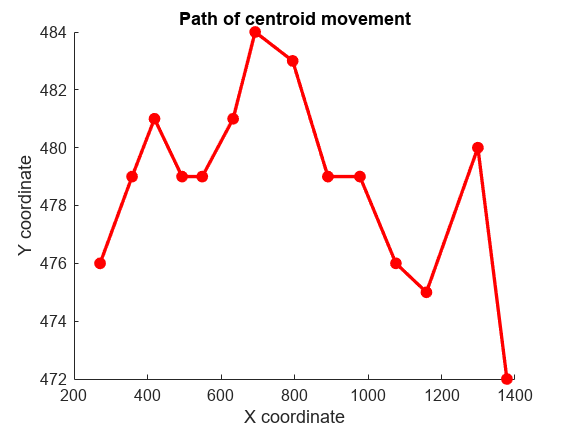




% Plot path of centroid movement
figure;
%imshow(img);
hold on;
plot(centroid_points(:,1), centroid_points(:,2), 'r', 'LineWidth', 2);
scatter(centroid_points(:,1), centroid_points(:,2), 50, 'r', 'filled');
%xlim([0, imgSize(2)]);
%ylim([0, imgSize(1)]);
title('Path of centroid movement');
xlabel('X coordinate');
ylabel('Y coordinate');
hold off;

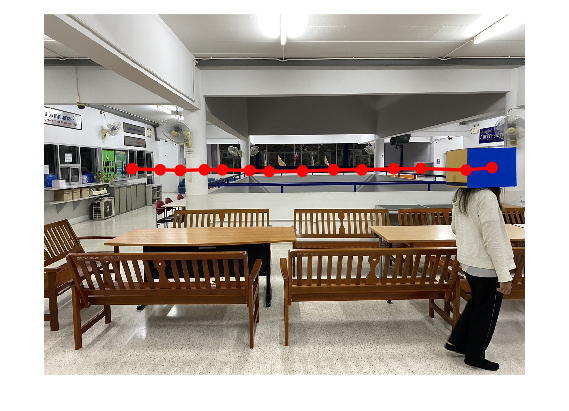


% Plot path of centroid movement
figure;
imshow(img);
hold on;
plot(centroid_points(:,1), centroid_points(:,2), 'r', 'LineWidth', 2);
scatter(centroid_points(:,1), centroid_points(:,2), 50, 'r', 'filled');
hold off;